# Signature Verification using Computer Vision Techniques

**Contents:**

- Add data folder to path

- Load images of forged and real signatures

- Detect features from signatures using:

- Harris Features

- Min Eigen Features

- SURF Features

- BRISK Features

- KAZE Features

          4. Find exact matching features

          5. Calculate the number of matched points

For the full details about each feature detection method, refer to this documentation: [https://www.mathworks.com/help/vision/feature-detection-and-extraction.html?s_tid=CRUX_lftnav.](https://www.mathworks.com/help/vision/feature-detection-and-extraction.html?s_tid=CRUX_lftnav.)

The dataset came from kaggle: *https://www.kaggle.com/divyanshrai/handwritten-signatures*

### Add Data Folder to Path

After downloading and extracting the dataset, make sure to add it to your current path.

%add your path here
addpath("forge")
addpath("real")

### Load Forged and Real Signature Images

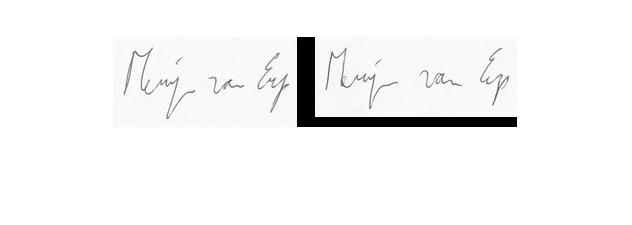

I1 = im2gray(imread('00101001.png'));
I2 = im2gray(imread('00102001.png')); 
imshowpair(I1,I2,'montage')

### Detect Features from Signatures

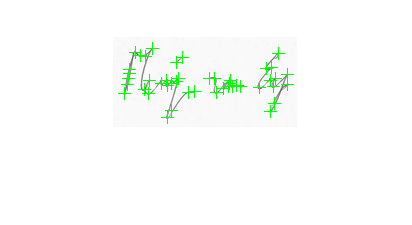

detectFeatures = @detectHarrisFeatures;
points1 = detectFeatures(I1); 
imshow(I1); hold on; plot(points1);hold off

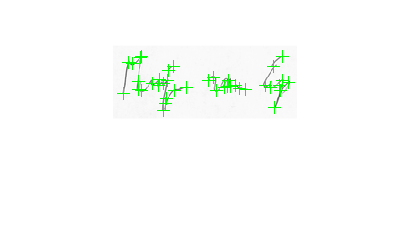

points2 = detectFeatures(I2);
imshow(I2); hold on; plot(points2); hold off

### Find Exact Matching Features

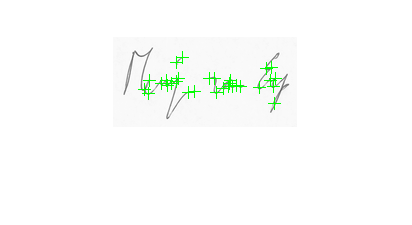

[features1,valid_points1] = extractFeatures(I1,points1);
imshow(I1); hold on; plot(valid_points1);hold off

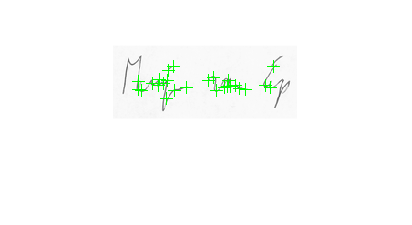

[features2,valid_points2] = extractFeatures(I2,points2);
imshow(I2); hold on; plot(valid_points2);hold off

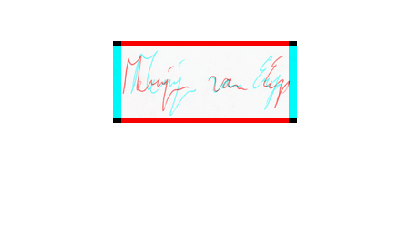

indexPairs = matchFeatures(features1,features2);

% extract match point
matchedPoints1 = valid_points1(indexPairs(:,1),:);
matchedPoints2 = valid_points2(indexPairs(:,2),:);

showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);

### Calculate the Number of Matched Points

u=matchedPoints2.Metric-matchedPoints1.Metric;
% set the threshold - the lower the better
if abs(u)<=0.04
    disp("Matched");
else
    disp("Not Matched");
end

Not Matched
